clear all
clc;

load('zzd.mat','zzd')
load('t.mat','t')
load('y_exprm.mat','y_exprm')
load('ut_save.mat','ut_save')

dist_ref  = [];
dist_expm = [];
% y_exprm__   = [y_exprm(1:end-1,:); y_exprm(end,:)];
% y_exprm__   = y_exprm(1:end-1,:);
% y_exprm__   = [zeros(1,3); y_exprm];
y_exprm__   = y_exprm;
y_exprm__(:,1:3)   = y_exprm__(:,1:3) * 1;
zzd__       = zzd * 1000;
t__         = [0, t];

% alpha       = -pi/15;
% R_z    = [cos(alpha),  sin(alpha), 0;...
%             -sin(alpha), cos(alpha), 0;...
%             0         , 0,         1];
% % % % beta       = +pi/200;
% % % % R_y    = [cos(beta), 0,  -sin(beta);...
% % % %             0,       1, 0;...
% % % %             sin(beta)    , 0,     cos(beta)];
% % % % gamma       = +pi/100;
% % % % R_x    = [ 1, 0,           0;...
% % % %            0, cos(gamma),  sin(gamma);...
% % % %            0, -sin(gamma), cos(gamma)];
% % % % 
% % % % % R_aft = R_y * R_z;
% R_aft = R_z;
% 
% for i = 1:size(y_exprm__,1)
%     y_exprm__(i,:) = (blkdiag(R_aft,R_aft,R_aft)*y_exprm(i,:)')';
% end
% % y_exprm__ = y_exprm;
% % y_exprm__(2:end,1) = y_exprm__(:,1)-y_exprm__(2,1);

% for i = 1:size(zzd__,2)
%     dist_ref  = [dist_ref,  norm(zzd__(:,i))];
%     dist_expm = [dist_expm, norm(y_exprm__(i,1:3))];
% end
% dist_error = abs(dist_ref - dist_expm);
dist_error = [];
for i = 1:size(zzd__,2)
    % dist_ref  = [dist_ref,  norm(zzd__(:,i))];
    % dist_expm = [dist_expm, norm(y_exprm__(i,1:3))];
    dist_error = [dist_error, norm(zzd__(:,i)' - y_exprm__(i,1:3))];
end
% dist_error = abs(dist_ref - dist_expm);
max(dist_error)

ans = single
46.1905

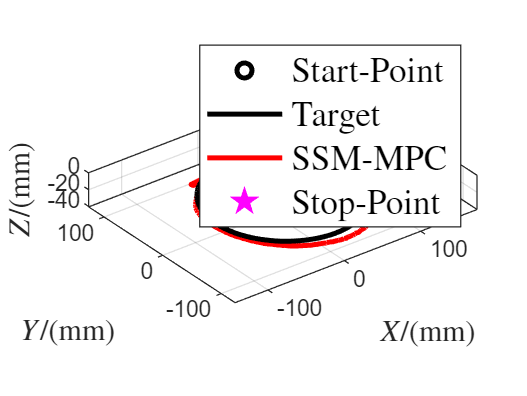

figure; hold on
scatter3(0,0,0,'ko',LineWidth=2,DisplayName='Start-Point')
% plot3(zzd__(1,1:100),zzd__(2,1:100),zzd__(3,1:100),'k-',LineWidth=2,DisplayName='Target')
% plot3(y_exprm__(1:100,1),y_exprm__(1:100,2),y_exprm__(1:100,3),'r-',LineWidth=2,DisplayName='SSM-MPC')
plot3(zzd__(1,:),zzd__(2,:),zzd__(3,:),'k-',LineWidth=2,DisplayName='Target')
% scatter3(zzd__(1,end),zzd__(2,end),zzd__(3,end),'kd',LineWidth=2,DisplayName='Target')
plot3(y_exprm__(:,1),y_exprm__(:,2),y_exprm__(:,3),'r-',LineWidth=2,DisplayName='SSM-MPC')
scatter3(y_exprm__(end,1),y_exprm__(end,2),y_exprm__(end,3),'mp',LineWidth=2, DisplayName='Stop-Point')

% grid on
xlabel('$X$/(mm)',Interpreter='latex',FontSize=12)
ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
zlabel('$Z$/(mm)',Interpreter='latex',FontSize=12)

legend('show',Interpreter='latex',fontsize=14)
box on
grid on
axis equal
view(3)

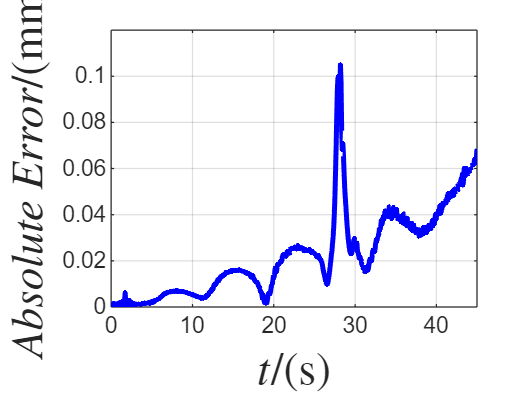

figure;
% subplot(3,1,1)
plot(t__,dist_error ./ 440,'b-',LineWidth=2)
xlim([t__(1),t__(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=18)
ylabel('$Absolute$ $Error$/(mm)',Interpreter='latex',FontSize=18)


% subplot(3,1,2)
% plot(t__,dist_error/430.*100,'b-',LineWidth=2)
% xlim([t__(1),t__(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
% ylabel('$Relative$ $Error$/(\%)',Interpreter='latex',FontSize=10)

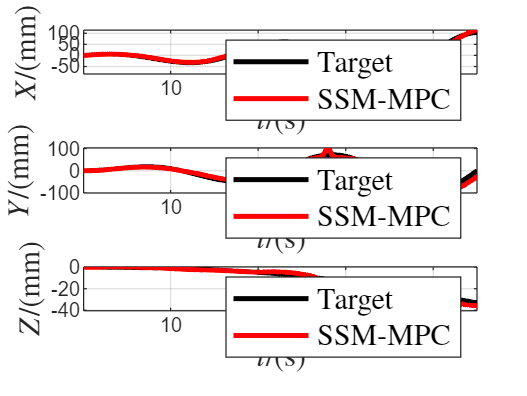

figure; 
subplot(3,1,1); hold on
plot(t__,zzd__(1,:),'k-',LineWidth=2,DisplayName='Target')
plot(t__,y_exprm__(:,1),'r-',LineWidth=2,DisplayName='SSM-MPC')
xlim([t(1)-0.001,t(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$X$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=12)
box on

subplot(3,1,2); hold on
plot(t__,zzd__(2,:),'k-',LineWidth=2,DisplayName='Target')
plot(t__,y_exprm__(:,2),'r-',LineWidth=2,DisplayName='SSM-MPC')
xlim([t(1)-0.001,t(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$Y$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=12)
box on

subplot(3,1,3); hold on
plot(t__,zzd__(3,:),'k-',LineWidth=2,DisplayName='Target')
plot(t__,y_exprm__(:,3),'r-',LineWidth=2,DisplayName='SSM-MPC')
xlim([t(1)-0.001,t(end)])
grid on
xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
ylabel('$Z$/(mm)',Interpreter='latex',FontSize=12)
legend('show',Interpreter='latex',fontsize=12)
box on

% figure; hold on
% plot(t__,zzd__(1,:),'r--',LineWidth=4,DisplayName='Target')
% plot(t__,y_exprm__(:,1),'b-',LineWidth=4,DisplayName='SSM-MPC')
% xlim([t(1)-0.001,t(end)])
% % grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
% ylabel('X/(mm)',Interpreter='latex',FontSize=12)
% legend('show',Interpreter='latex',fontsize=12)
% plot_setting
% 
% figure; hold on
% plot(t__,zzd__(2,:),'r--',LineWidth=4,DisplayName='Target')
% plot(t__,y_exprm__(:,2),'b-',LineWidth=4,DisplayName='SSM-MPC')
% xlim([t(1)-0.001,t(end)])
% % grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=12)
% ylabel('Y/(mm)',Interpreter='latex',FontSaize=12)
% legend('show',Interpreter='latex',fontsize=12)
% plot_setting
% 

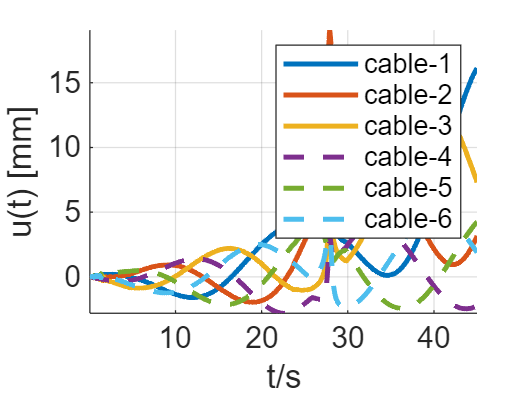

figure; hold on  
plot(t, ut_save(1:3,:),'-',LineWidth=2)
plot(t, ut_save(4:6,:),'--',LineWidth=2)
grid on, axis tight
set(gca,'FontSize',12); grid on, axis tight

legend(["cable-1","cable-2","cable-3","cable-4","cable-5","cable-6"])
xlabel('t/s')
ylabel('u(t) [mm]')